# CoM Trajectory Calculator

#### 아래 Data들의 저장순서는 다음과 같다.

#### [Body, TAR, TAL, TPR, TPL, CR, CL]

clc;clear;close;

load('dynamic_properties.mat');

% link_parameter
properties.a = 75 * cos(pi/6);
properties.b = 75 * sin(pi/6);
properties.l1 = 106;
properties.l2 = 77;
properties.l3 = 50;
properties.l4 = 137;
properties.l5 = 8;
 
% wheel width
properties.L = 123;

% % 각 link들의 CoM Offset
% properties.c_vectors = ones(3,7);
% 
% % 각 link들의 mass
% properties.masses = ones(7,1) * 0.25;
% 
% % 각 link들의 CoM 기준 Inertia Tensor
% properties.IG_matrices = zeros(3,3,7);
% for i = 1:7
%     properties.IG_matrices(:,:,i) = eye(3,3);
% end

% 각 link들의 CoM Offset (순서: [Body, TAR, TAL, TPR, TPL, CR, CL])
properties.c_vectors = [
    center_of_mass_MainBody, ...
    center_of_mass_ThighLink_Active_Right, ...
    center_of_mass_ThighLink_Active_Left, ...
    center_of_mass_ThighLink_Passive_Right, ...
    center_of_mass_ThighLink_Passive_Left, ...
    center_of_mass_Calf_Link_Right, ...
    center_of_mass_Calf_Link_Left
];

% 각 link들의 질량 (순서: [Body, TAR, TAL, TPR, TPL, CR, CL])
properties.masses = [
    mass_of_Mainbody, ...
    mass_of_ThighLink_Active_Right, ...
    mass_of_ThighLink_Active_Left, ...
    mass_of_ThighLink_Passive_Right, ...
    mass_of_ThighLink_Passive_Left, ...
    mass_of_Calf_Link_Right, ...
    mass_of_Calf_Link_Left
];

% 각 link들의 CoM 기준 관성 모멘트 텐서 (순서: [Body, TAR, TAL, TPR, TPL, CR, CL])
properties.IG_matrices(:,:,1) = inertia_tensor_MainBody;
properties.IG_matrices(:,:,2) = inertia_tensor_ThighLink_Active_Right;
properties.IG_matrices(:,:,3) = inertia_tensor_ThighLink_Active_Left;
properties.IG_matrices(:,:,4) = inertia_tensor_ThighLink_Passive_Right;
properties.IG_matrices(:,:,5) = inertia_tensor_ThighLink_Passive_Left;
properties.IG_matrices(:,:,6) = inertia_tensor_Calf_Link_Right;
properties.IG_matrices(:,:,7) = inertia_tensor_Calf_Link_Left;



% theta_hips limit - [-69.97, 29.68]
hs = 60:0.001:200;
hs = hs';

theta_hipL_IK_sol = zeros(length(hs),1);
hL_FK_sol = zeros(length(hs), 1);
for i = 1:length(hs)
    theta_hips = solve_inverse_kinematics(hs(i), 0, properties);
    theta_hipL_IK_sol(i) = theta_hips(2);
    [~, ~, ~, ~, e_poses] = solve_forward_kinematics(theta_hips, properties);
    hL_FK_sol(i) = -e_poses(2,2);
end

다음 사용 중 오류가 발생함: Calculate_CoM_Trajectory>solve_forward_kinematics
Ratio exceeds valid range. Check input parameters or theta_hips.


% 그래프 그리기
figure('Color', 'w', 'Units', 'normalized', 'OuterPosition', [0 0 0.8 0.6]);

subplot(1,2,1);
% Plot 1: Inverse Kinematics (IK) Solution
plot(rad2deg(theta_hipL_IK_sol), hs, 'LineWidth', 2, 'DisplayName', 'IK Solution');
hold on;

% Plot 2: Forward Kinematics (FK) Solution
plot(rad2deg(theta_hipL_IK_sol), hL_FK_sol, 'LineWidth', 2, 'DisplayName', 'FK Solution');

% 그래프 꾸미기
title('Hip Angle vs Height', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Hip Angle (\theta_{hipL}) [deg]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Height (h) [mm]', 'FontSize', 12, 'FontWeight', 'bold');
grid on;
legend('Location', 'best', 'FontSize', 12); % 자동으로 적절한 위치 선정

% 추가 시각적 요소
set(gca, 'FontSize', 12, 'FontWeight', 'bold', 'GridAlpha', 0.3, 'LineWidth', 1.2); % 축 스타일
box on; % 그래프 테두리 활성화
hold off;

subplot(1,2,2);
% Plot 1: Inverse Kinematics (IK) Solution
plot(rad2deg(theta_hipL_IK_sol), hL_FK_sol - hs, 'LineWidth', 2);

% 그래프 꾸미기
title('Hip Angle vs error', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('Hip Angle (\theta_{hipL}) [deg]', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('error [mm]', 'FontSize', 12, 'FontWeight', 'bold');
grid on;

% 추가 시각적 요소
set(gca, 'FontSize', 12, 'FontWeight', 'bold', 'GridAlpha', 0.3, 'LineWidth', 1.2); % 축 스타일
box on; % 그래프 테두리 활성화
hold off;

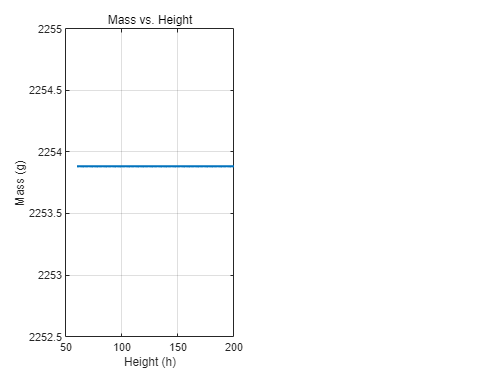


h = 60:0.5:200;
phi = 0;
mass_totals = zeros(length(h),1);
r_totals = zeros(length(h),3);
I_totals = zeros(3, 3, length(h));  % 관성 텐서 배열

% 각 h에 대해 물리적 특성 계산
for i = 1:length(h)
    [mass_total, r_total, I_total] = calculate_body_total_property(h(i), phi, properties);
    
    mass_totals(i) = mass_total;  % 질량 저장
    r_totals(i, :) = r_total';    % CoM 위치 저장
    I_totals(:, :, i) = I_total; % 관성 텐서 저장
end

% Figure 생성
figure;

% 1. 질량 시각화 (2D 플롯) - Subplot 1
ax1 = subplot(1,2,1);
plot(ax1, h, mass_totals, 'LineWidth', 2);
xlabel(ax1, 'Height (h)');
ylabel(ax1, 'Mass (g)');
title(ax1, 'Mass vs. Height');
grid(ax1, 'on');

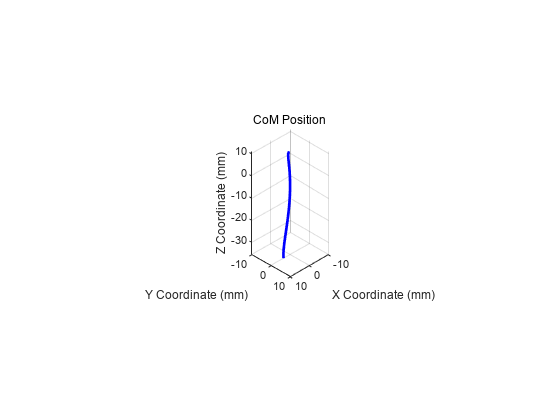


% 2. r_totals 시각화 (3D 곡선) - Subplot 2
ax2 = subplot(1,3,2);
plot3(ax2, r_totals(:,1), r_totals(:,2), r_totals(:,3), 'b'  , 'LineWidth', 2);
xlabel(ax2, 'X Coordinate (mm)');
ylabel(ax2, 'Y Coordinate (mm)');
zlabel(ax2, 'Z Coordinate (mm)');
title(ax2, 'CoM Position');
grid(ax2, 'on');
axis(ax2, 'vis3d');
axis(ax2, 'equal');
view(ax2, [1,1,1]);
xlim(ax2, [-10, 10]);
ylim(ax2, [-10, 10]);

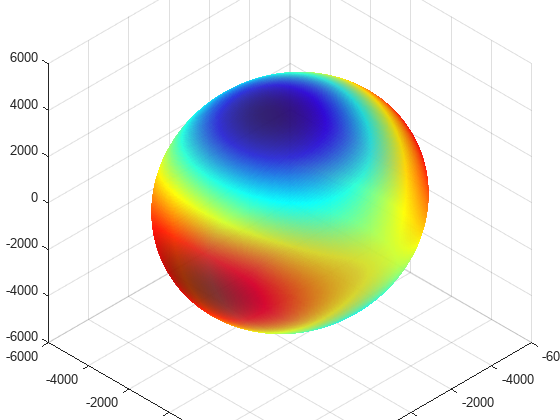


figure;
% 3. I_totals 시각화 (애니메이션, 알록달록한 타원체 표시) - Subplot 3
ax3 = subplot(1,1,1);
grid(ax3, 'on');
xlabel(ax3, 'X');
ylabel(ax3, 'Y');
zlabel(ax3, 'Z');
title(ax3, 'Inertia Tensor Ellipsoid Animation');
hold(ax3, 'on');
axis(ax3, 'vis3d');
axis(ax3, 'equal');
view(ax3, [1,1,1]);

% 절댓값 최대값 계산
max_abs_value = 0;
for i = 1:length(h)
    [eigenvectors, eigenvalues] = eig(I_totals(:,:,i));
    radii = sqrt(diag(eigenvalues)); % 타원체의 반지름
    max_abs_value = max(max_abs_value, max(radii));
end

% 축 제한 설정
xlim(ax3, [-max_abs_value, max_abs_value]);
ylim(ax3, [-max_abs_value, max_abs_value]);
zlim(ax3, [-max_abs_value, max_abs_value]);

% 타원체 초기화
[ellipsoid_x, ellipsoid_y, ellipsoid_z] = ellipsoid(0, 0, 0, 1, 1, 1, 300);
h_ellipsoid = surf(ax3, ellipsoid_x, ellipsoid_y, ellipsoid_z, ...
                   'FaceAlpha', 0.8, 'EdgeColor', 'none');
colormap(ax3, jet); % 컬러맵 설정


% 한 프레임의 시간 설정 (초 단위)
target_time = 0.005;  % 목표 시간 (예: 0.05초 = 20 FPS)

% 무한 반복 애니메이션
while true
    for i = 1:length(h)
        % 루프 시작 시간 기록
        tic;
        
        % 고유값과 고유벡터 계산
        [eigenvectors, eigenvalues] = eig(I_totals(:,:,i));
        radii = sqrt(diag(eigenvalues)); % 타원체의 반지름
        
        % 변환 행렬 적용 (고유벡터 기반)
        transformed_coords = eigenvectors * [radii(1) * ellipsoid_x(:)'; 
                                             radii(2) * ellipsoid_y(:)'; 
                                             radii(3) * ellipsoid_z(:)'];
        
        % 재구성된 타원체 좌표
        transformed_x = reshape(transformed_coords(1, :), size(ellipsoid_x));
        transformed_y = reshape(transformed_coords(2, :), size(ellipsoid_y));
        transformed_z = reshape(transformed_coords(3, :), size(ellipsoid_z));
        
        % 거리 데이터 정규화 (비율로 변환)
        ellipsoid_c = sqrt(transformed_x.^2 + transformed_y.^2 + transformed_z.^2);
        ellipsoid_c_normalized = (ellipsoid_c - min(ellipsoid_c(:))) / ...
                                 (max(ellipsoid_c(:)) - min(ellipsoid_c(:)));
        
        % 타원체 업데이트
        set(h_ellipsoid, 'XData', transformed_x, ...
                         'YData', transformed_y, ...
                         'ZData', transformed_z, ...
                         'CData', ellipsoid_c_normalized);
        
        % 루프 실행 시간이 target_time보다 길면, 차이만큼 대기
        elapsed_time = toc;  % 루프 실행 시간 측정
        pause_time = target_time - elapsed_time;  % 대기 시간 계산
        
        if pause_time > 0
            pause(pause_time);  % 남은 시간만큼 대기
        end
        
        % 애니메이션 최적화
        drawnow limitrate; 
    end
end




**p_vectors Generator**

input : $h$, $\phi$

output : p_vectors

height과 roll angle을 받아서, origin position vector들의 집합인 p_vectors를 생성

p_vectors의 순서는 다음과 같다.

[Body, TAR, TAL, TPR, TPL, CR, CL]

function p_vectors = calculate_p_vectors(theta_hips, properties)

p_vectors = zeros(3,7);
[~, ~, ~, c_poses] = solve_forward_kinematics(theta_hips, properties);
c_posR = c_poses(:,1);
c_posL = c_poses(:,2);

% Body
p_vectors(:,1) = [0; 0; 0];
% TAR
p_vectors(:,2) = [-64.951905284 ; -86; 37.5];
% TAL
p_vectors(:,3) = [-64.951905284 ; 86; 37.5];
% TPR
p_vectors(:,4) = [0; -81; 0];
% TPL
p_vectors(:,5) = [0; 81; 0];
% CR
p_vectors(:,6) = [c_posR(1); -102; c_posR(2)];
% CL
p_vectors(:,7) = [c_posL(1); 102; c_posL(2)];

end

**R_matrices Generator**

right과 left의 hip angle을 받아서 link들의 Orientation을 나타내는 Rotation matrix의 집합인 R_matrices를 생성

R_matrices의 순서는 다음과 같다.

[Body, TAR, TAL, TPR, TPL, CR, CL]

function R_matrices = calculate_R_matrices(theta_hips, properties)
    R_matrices = zeros(3,3,7);
    [theta_As, theta_Bs, theta_ks, ~] = solve_forward_kinematics(theta_hips, properties);
    % Body
    R_matrices(:,:,1) = eye(3,3);
    % TAR
    R_matrices(:,:,2) = rotation_matrix_y(theta_Bs(1));
    % TAL
    R_matrices(:,:,3) = rotation_matrix_y(theta_Bs(2));
    % TPR
    R_matrices(:,:,4) = rotation_matrix_y(theta_As(1));
    % TPL
    R_matrices(:,:,5) = rotation_matrix_y(theta_As(2));
    % CR
    R_matrices(:,:,6) = rotation_matrix_y(theta_ks(1));
    % CL
    R_matrices(:,:,7) = rotation_matrix_y(theta_ks(2));
end

function R = rotation_matrix_y(theta)
    % 회전 각도 theta에 대한 y-axis 회전 행렬
    % theta는 라디안 단위로 입력
    
    R = [cos(theta), 0, sin(theta);
         0, 1, 0;
         -sin(theta), 0, cos(theta)];
end

function [mass_total, r_total, I_total] = calculate_body_total_property(h, phi, properties)
% 주어진 height과 roll angle에 대해서, system의 Inertia tensor를 계산한다. 이때 frame과 중심은 IMU를 기준으로 한다.
    theta_hips = solve_inverse_kinematics(h, phi, properties);
    
    % Extract properties
    c_vectors = properties.c_vectors;
    masses = properties.masses;
    IG_matrices = properties.IG_matrices;

    mass_total = sum(masses);

    p_vectors = calculate_p_vectors(theta_hips, properties);
    R_matrices = calculate_R_matrices(theta_hips, properties);
    r_total = zeros(3,1);
    I_total = zeros(3,3);

    % calculate Body_CoM_offset
    for i = 1:7
        r_Bi = p_vectors(:,i) + R_matrices(:,:,i) * c_vectors(:,i);
        r_total = r_total + masses(i) * r_Bi;
    end
    r_total = r_total / mass_total;

    % calculate Body_CoM_Inertia_Tensor
    for i = 1:7
        p = p_vectors(:,i);
        R = R_matrices(:,:,i);
        c = c_vectors(:,i);
        m = masses(i);
        
        IG_ii = IG_matrices(:,:,i);
        r_Bi = p + R * c;
        r_CoMi = r_Bi - r_total;

        IG_Bi =  R * IG_ii * R' + m*(norm(r_CoMi)^2*eye(3,3) - r_CoMi * r_CoMi'); 
        I_total = I_total + IG_Bi;
    end
end

function [theta_As, theta_Bs, theta_ks, c_poses, e_poses] = solve_forward_kinematics(theta_hips, properties)
    % theta_hips = [theta_hipR; theta_hipL]

    % Extract link length
    a = properties.a;
    b = properties.b;
    l1 = properties.l1;
    l2 = properties.l2;
    l3 = properties.l3;
    l4 = properties.l4;
    l5 = properties.l5;

    % 계산을 위해 두 hip 각도를 사용
    theta_Bs = [-theta_hips(1); theta_hips(2)]; % BR, BL 각도

    % L1, L2 계산
    L1 = sqrt((a + l2 * cos(theta_Bs)).^2 + (b + l2 * sin(theta_Bs)).^2); % 거리 계산
    L2 = (a^2 + b^2 + l1^2 + l2^2 - l3^2 + 2*l2.*(a*cos(theta_Bs) + b*sin(theta_Bs))) / (2 * l1);

    % Ratio 확인 및 예외 처리
    ratio = L2 ./ L1;
    if any(abs(ratio) > 1)
        error('Ratio exceeds valid range. Check input parameters or theta_hips.');
    end

    % 각도 계산
    alpha = atan2(b + l2 * sin(theta_Bs), a + l2 * cos(theta_Bs)); % atan2로 정확한 사분면 계산
    theta_As = -acos(ratio) + alpha; % 각도 A 계산

    % 무릎 각도 계산
    theta_ks = atan2((b + l2 * sin(theta_Bs) - l1 * sin(theta_As)), ...
                     (a + l2 * cos(theta_Bs) - l1 * cos(theta_As))); % 무릎 각도
   
    % C 위치 계산
    c_poses = [-a - l2 * cos(theta_Bs), b + l2 * sin(theta_Bs)]'; % 좌표 계산

    e_poses = [-l1 * cos(theta_As) + l4 * cos(theta_ks) + l5 * sin(theta_ks), ...
                l1 * sin(theta_As) - l4 * sin(theta_ks) + l5 * cos(theta_ks)]';
   
end

function theta_hips = solve_inverse_kinematics(h, phi, properties)
    % Extract link length
    a = properties.a;
    b = properties.b;
    l1 = properties.l1;
    l2 = properties.l2;
    l3 = properties.l3;
    l4 = properties.l4;
    l5 = properties.l5;

    L = properties.L;
    
    % h_saturation 설정
    phi_max = min(atan((h - 60) / L), atan((200 - h) / L));
    phi_min = -phi_max;
    
    if phi > phi_max
        phi = phi_max;
    elseif phi < phi_min
        phi = phi_min;
    end
    hR = h - L*tan(phi);
    hL = h + L*tan(phi);

    hs = [hR; hL];

    
    AB = sqrt(a^2 + b^2);
    angle_ADE = acos((l1^2 + l4^2 + l5^2 - hs.^2) / (2 * l1 * sqrt(l4^2 + l5^2)));
    angle_EDF = atan(l5 / l4);
    angle_ADC = pi - (angle_ADE + angle_EDF);
    AC = sqrt(l1^2 + l3^2 - 2 * l1 * l3 * cos(angle_ADC));

    S = (AB^2 + l2^2 - AC.^2) / (2 * AB * l2);

    % 요소별로 조건 확인
    invalid_indices = abs(S) > 1 & abs(AC - sqrt(a^2 + b^2) - l2) < 0.1;
    for i = 1:length(S)
        if invalid_indices(i)
            AC(i) = sqrt(a^2 + b^2) + l2;
            S(i) = 1;
        end
    end
    angle_ABC = acos((AB^2 + l2^2 - AC.^2) / (2 * AB * l2));
    theta_hips = (5 * pi / 6) - angle_ABC;

    theta_hips(2) = -theta_hips(2);
end